%%lab3


clear variables
clc
syms x

f = asin(2*x+3);
diff(f);

f1 = atan(x^2+1);
diff(f1);

f2=int(x*sin(x^2));

f3=x^2*(sqrt(x+4));
int(f3);

syms u w l g

uw = dsolve('Du = w','Dw = -0.05*w-g/l*u','u(0)=4','w(0)=0')

uw = struct with fields:
    w: (80*g*exp(-(t*(l + (-l*(1600*g - l))^(1/2)))/(40*l)))/(-l*(1600*g - l))^(1/2) - (80*g*exp(-(t*(l - (-l*(1600*g - l))^(1/2)))/(40*l)))/(-l*(1600*g - l))^(1/2)
    u: (80*g*exp(-(t*(l + (-l*(1600*g - l))^(1/2)))/(40*l))*((l + (-l*(1600*g - l))^(1/2))/(40*g) - l/(20*g)))/(-l*(1600*g - l))^(1/2) - (80*g*exp(-(t*(l - (-l*(1600*g - l))^(1/2)))/(40*l))*((l - (-l*(1600*g - l))^(1/2))/(40*g) - l/(20*g)))/(-l*(1600…


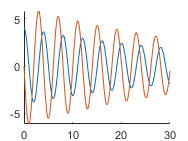

theta = subs(uw.u,{l,g},{4,9.8});
omega = subs(uw.w,{l,g},{4,9.8});
hold on
fplot(theta,[0,30]);
fplot(omega,[0,30]);
hold off


syms uLC;
syms iL;
syms iC;
R=100;
V=3.3;
L=0.033;
C=0.002;
diff(iL)=uLC/L

$$diff(iL) = \frac{1000\,\mathrm{uLC}}{33}$$

diff(uLC)=((V-uLC)/R-iL)/C

$$diff(uLC) = \frac{33}{2}-5\,\mathrm{uLC}-500\,\mathrm{iL}$$

iC=((V-uLC)/R-iL)

$$iC = \frac{33}{1000}-\frac{\mathrm{uLC}}{100}-\mathrm{iL}$$



grabcode("https://trupples.space/uni/2/ProcessModeling/html/lab4.html")
